if exist("data","var") == 0
    F0 = "/home/ccanodom/data/sweep_data/_new_current_profile_sweep_0_-5.csv";
    data = {};
    data{1} = importfile_pybamm(F0);
    F5 = "/home/ccanodom/data/sweep_data/_new_current_profile_sweep_5_0.csv";
    data{2} = importfile_pybamm(F5);
    F5 = "/home/ccanodom/data/sweep_data/_new_current_profile_sweep_7_2.csv";
    data{2} = importfile_pybamm(F5);
end



minimum = 100000;
for i=1:length(data)    
    minimum = min(minimum, max(data{i}.Cycle));
end
display(minimum);

minimum = 120

cycle = 11

cycle = 11

max(data{2 }.Cycle)

ans = 160

Coefficients (a, b, k):
   -0.1019   12.2516   -0.0319

Goodness of fit:
           sse: 2.3796
       rsquare: 0.9952
           dfe: 19166
    adjrsquare: 0.9952
          rmse: 0.0111



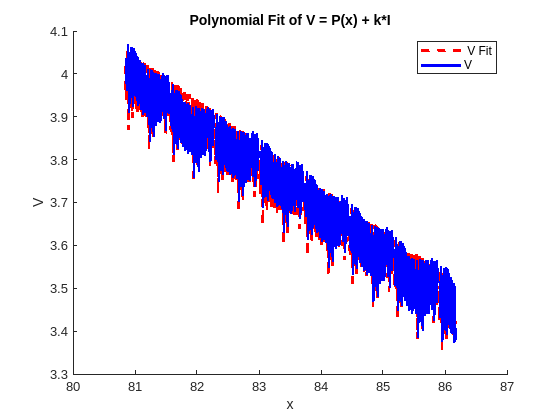


figure
fit_udds(data{2}, 40 ...
    )

Coefficients (a, b, k, p, n):
   -0.1544  370.3487   -0.0366  366.2527    0.0001

Goodness of fit:
           sse: 19.3481
       rsquare: 0.9711
           dfe: 19162
    adjrsquare: 0.9710
          rmse: 0.0318



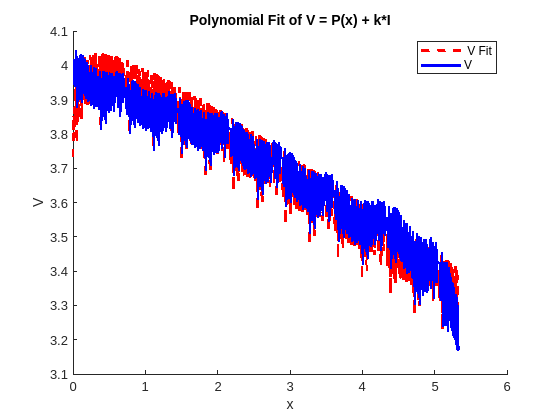

figure
fit_udds_exp(data{2}, 160 )

Coefficients (a, b, k, p, n):
   1.0e+03 *

   -0.0006    0.0915   -0.0000    3.3295

Goodness of fit:
           sse: 4.0622
       rsquare: 0.9928
           dfe: 19241
    adjrsquare: 0.9928
          rmse: 0.0145



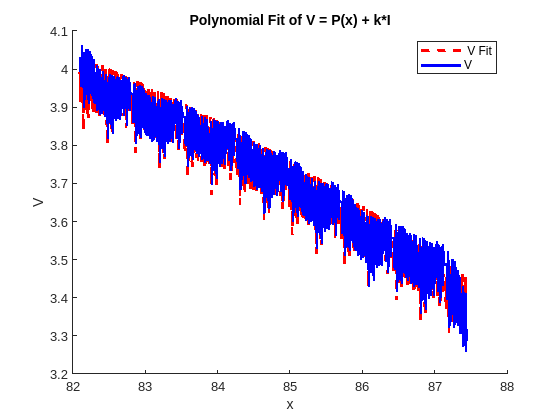

figure
fit_udds_exp(data{2}, 100 )

Coefficients (a, b, k, p, n):
   1.0e+03 *

   -0.0001    1.2637   -0.0000    1.2593   -0.0000

Goodness of fit:
           sse: 1.5077
       rsquare: 0.9967
           dfe: 19163
    adjrsquare: 0.9967
          rmse: 0.0089



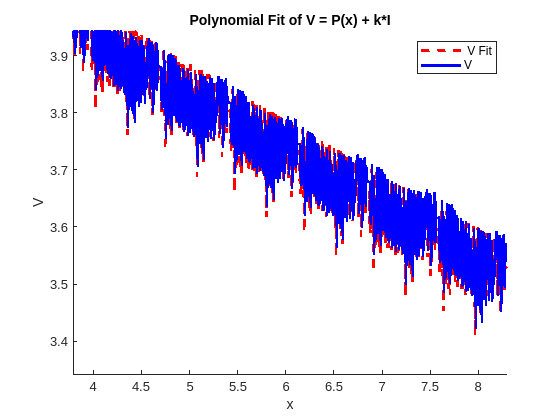

figure
fit_udds_exp(data{2}, 1 )

EV_data = import_EV_data("W04", 30);

current_data = EV_data(EV_data.Cycle == 100 & EV_data.Step == 5,:)

current_data = 6278×8 table
      t         V           C           D_cap        C_cap     Step    Cycle    relative_time
    ______    ______    __________    __________    _______    ____    _____    _____________

    351.56     3.975     0.0040894    7.8101e-07    0.97003     5       100        9.1795    
    351.56     3.978    -0.0050583    2.0016e-06    0.97003     5       100        9.1803    
    351.56    3.9822       -0.0504    3.6796e-05    0.97003     5       100        9.1812    
    351.56    3.9852     -0.051025    7.9831e-05    0.97003     5       100         9.182    
    351.56    3.9864     -0.052956    0.00012268    0.97003     5       100        9.1828    
    351.56     3.988     -0.051231    0.0

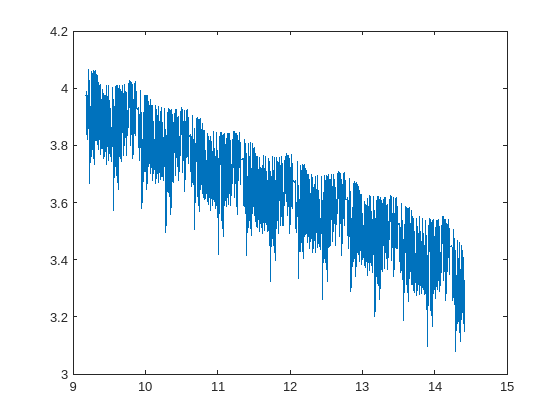

plot(current_data.relative_time, current_data.V)

Coefficients (a, b, k, p, n):
   -0.1132    3.9729   -0.0338   -0.0085    0.2105

Goodness of fit:
           sse: 0.4690
       rsquare: 0.9705
           dfe: 2548
    adjrsquare: 0.9705
          rmse: 0.0136



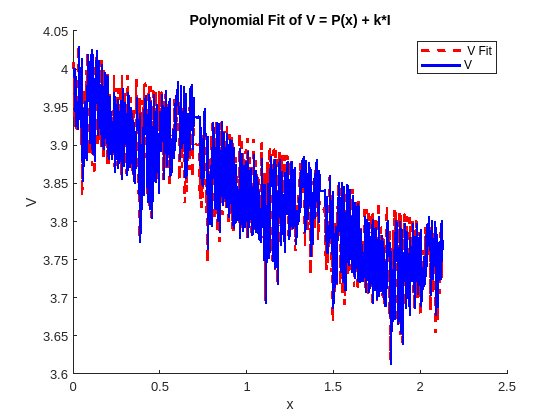

fit_udds_exp(EV_data, 152)